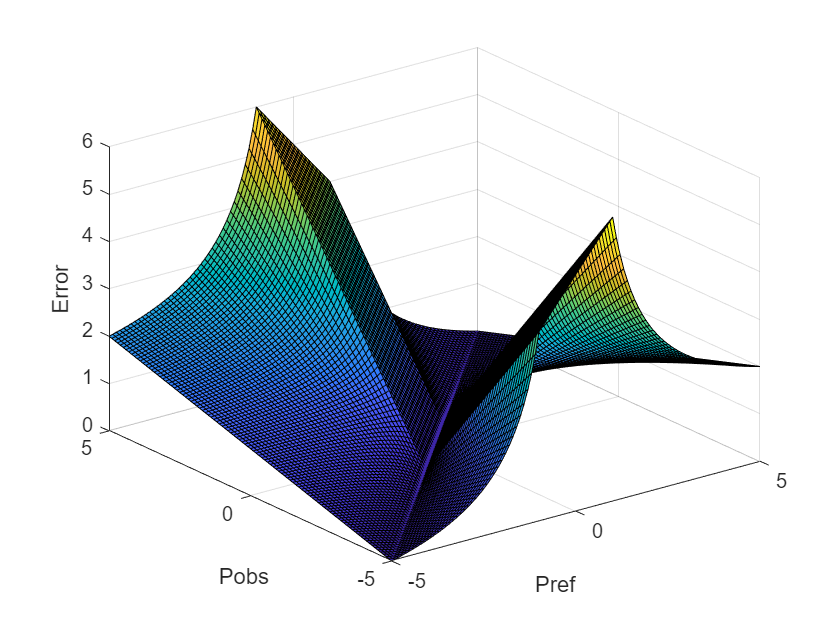

%Error functions testing

%Parameters
%We just need to observe the behavior betwween
%this iteration
%clc; clear;
x = -5:0.1:5;
y = -5:0.1:5;
%fixX = ones(201, 201);
%fixX =  fixX *5;
[Pobs, Pref] = ndgrid(x,y);


%First error funtion
%Relative error

% for i = 1:101
%     Pref(i,51) = 0.005;
% end

for i = 1:101
    for j = 1:101
        if(abs(Pref(i,j))>=1)
            err1(i,j) = abs(Pref(i,j)-Pobs(i,j))/abs(Pref(i,j));
        else
            err1(i,j) = abs(Pref(i,j)-Pobs(i,j));
        end
    end
end

for i = 1:101
    for j = 1:101
            err2(i,j) = abs(Pref(i,j)-Pobs(i,j))/max(abs(Pref(i,j)),1);
    end
end

%err1 = (abs(Pref-Pobs)./(Pref));
figure
surf(Pref, Pobs, err1);
xlabel('Pref'), ylabel('Pobs'), zlabel('Error');

figure
surf(Pref, Pobs, err2);
xlabel('Pref'), ylabel('Pobs'), zlabel('Error');